## Code to filter water level data

cd 'G:\My Drive\PhD_Research\BSF_Thesis\ModernAndSurfaceProcesses\Analyses\ModProcAnalyses\Groundwater'
cd ThermalEfficiency\data\input\
load('Bflat30min.mat')
load('BLM93_AirPresCor.mat')
load('BLM93C_AirPresCor.mat')
load('BLM41_AirPresCor.mat')
load('BLM31_AirPresCor.mat')

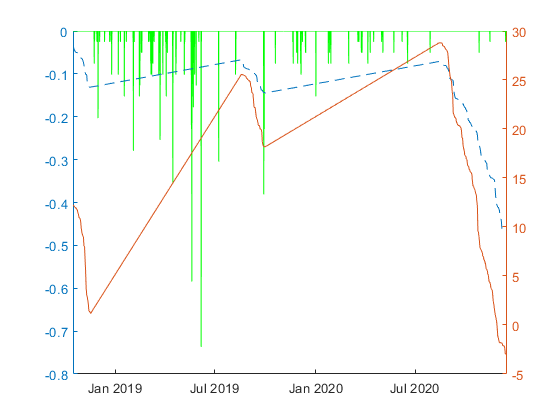

well = BLM93;

well = retime(well, "weekly",'mean');
well.SoilTemp_C = smoothdata(well.SoilTemp_C,'movmedian','SmoothingFactor',0.05,...
    'SamplePoints',well.Date_Time_MDT);
well.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor = ...
    smoothdata(well.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor,...
    'movmedian','SmoothingFactor',0.05,'SamplePoints',well.Date_Time_MDT);

well = well(well.Date_Time_MDT >= datetime('2018-10-16','InputFormat','yyyy-MM-dd') , :);

idx = well.Date_Time_MDT >= datetime('2018-11-18','InputFormat','yyyy-MM-dd') & ...
    well.Date_Time_MDT <= datetime('2019-08-18','InputFormat','yyyy-MM-dd');
well = well(~idx, :);

idx = well.Date_Time_MDT >= datetime('2019-10-02','InputFormat','yyyy-MM-dd') & ...
    well.Date_Time_MDT <= datetime('2020-08-12','InputFormat','yyyy-MM-dd');
well = well(~idx, :);

well = well(well.Date_Time_MDT <= datetime('2020-12-15','InputFormat','yyyy-MM-dd') , :);

figure
hold on
yyaxis left
plot(Bflat30min.Date_Time_MDT, -Bflat30min.PPT_mm/10, 'color', 'green')
plot(well.Date_Time_MDT, -well.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor)

yyaxis right
plot(well.Date_Time_MDT, well.SoilTemp_C)

xlim(well.Date_Time_MDT([1,end]))

BLM93 = well;

BLM93 = 202×20 timetable
       Date_Time_MDT        WaterTemp_C_extrap_200cm    WaterTemp_C_extrap_100cm    WaterTemp_C_extrap_50cm    WaterTemp_C_extrap_25cm    Temp_C_SN20213984_May2018_August2018_344cm    Temp_C_SN20213982_May2018_August2018_247cm    Temp_C_SN20213983_May2018_August2018_170cm    Temp_C_SN20029191_May2018_August2018_90cm    Temp_C_SN20214184_May2018_August2018_38cm    WaterTemp_C_extrap_245cm    Temp_C_SN20214184_November2020_December2020_266cm    Temp_C_SN20925224_November2020_December2020_159cm    EquivalentHead    WaterLevelBelowSurface_m    WaterTemp_C    TDdepth_m    EquivalentHead_HaliteSaturated_BelowSurf_m    AirTemp1_C    SoilTemp_C

cd cropped\
save("BLM93clipped.mat", 'BLM93')

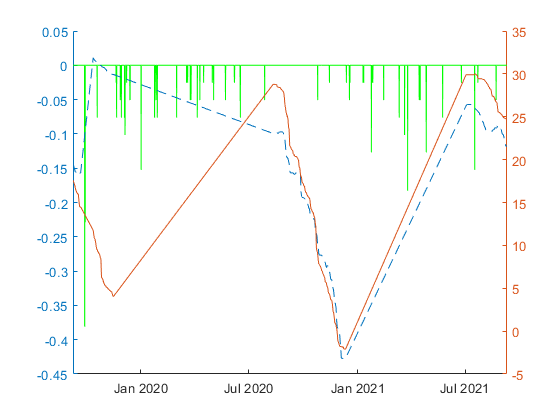

well = BLM93C;

well = retime(well, "daily",'mean');
well.SoilTemp_C = smoothdata(well.SoilTemp_C,'movmedian','SmoothingFactor',0.05,...
    'SamplePoints',well.Date_Time_MDT);
well.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor = ...
    smoothdata(well.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor,...
    'movmedian','SmoothingFactor',0.05,'SamplePoints',well.Date_Time_MDT);

idx = well.Date_Time_MDT >= datetime('2019-09-23','InputFormat','yyyy-MM-dd') & ...
    well.Date_Time_MDT <= datetime('2019-10-12','InputFormat','yyyy-MM-dd');
well = well(~idx, :);
% 
idx = well.Date_Time_MDT >= datetime('2019-11-17','InputFormat','yyyy-MM-dd') & ...
    well.Date_Time_MDT <= datetime('2020-08-10','InputFormat','yyyy-MM-dd');
well = well(~idx, :);
% 
idx = well.Date_Time_MDT >= datetime('2020-12-12','InputFormat','yyyy-MM-dd') & ...
    well.Date_Time_MDT <= datetime('2021-07-01','InputFormat','yyyy-MM-dd');
well = well(~idx, :);

figure
hold on
yyaxis left
plot(Bflat30min.Date_Time_MDT, -Bflat30min.PPT_mm/10, 'color', 'green')
plot(well.Date_Time_MDT, -well.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor)

yyaxis right
plot(well.Date_Time_MDT, well.SoilTemp_C)

xlim(well.Date_Time_MDT([1,end]))

BLM93C = well;
cd cropped\
save("BLM93Cclipped.mat", 'BLM93C')

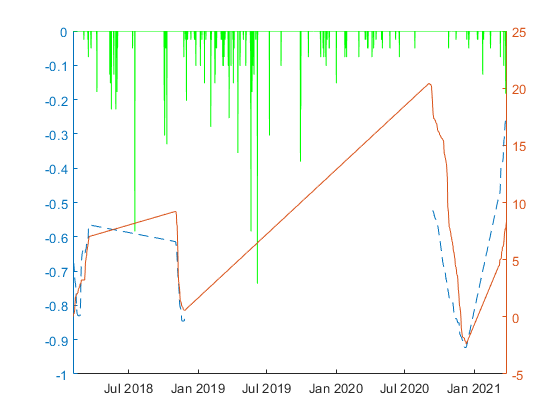

well = BLM41;

well = retime(well, "daily",'mean');
well.SoilTemp_C = smoothdata(well.SoilTemp_C,'movmedian','SmoothingFactor',0.05,...
    'SamplePoints',well.Date_Time_MDT);
well.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor = ...
    smoothdata(well.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor,...
    'movmedian','SmoothingFactor',0.05,'SamplePoints',well.Date_Time_MDT);

well = well(well.Date_Time_MDT >= datetime('2018-02-03','InputFormat','yyyy-MM-dd') , :);

idx = well.Date_Time_MDT >= datetime('2018-03-19','InputFormat','yyyy-MM-dd') & ...
    well.Date_Time_MDT <= datetime('2018-11-01','InputFormat','yyyy-MM-dd');
well = well(~idx, :);

idx = well.Date_Time_MDT >= datetime('2018-11-27','InputFormat','yyyy-MM-dd') & ...
    well.Date_Time_MDT <= datetime('2020-09-01','InputFormat','yyyy-MM-dd');
well = well(~idx, :);

idx = well.Date_Time_MDT >= datetime('2020-12-12','InputFormat','yyyy-MM-dd') & ...
    well.Date_Time_MDT <= datetime('2021-03-05','InputFormat','yyyy-MM-dd');
well = well(~idx, :);

well = well(well.Date_Time_MDT <= datetime('2021-03-29','InputFormat','yyyy-MM-dd') , :);

figure
hold on
yyaxis left
plot(Bflat30min.Date_Time_MDT, -Bflat30min.PPT_mm/10, 'color', 'green')
plot(well.Date_Time_MDT, -well.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor)

yyaxis right
plot(well.Date_Time_MDT, well.SoilTemp_C)

xlim(well.Date_Time_MDT([1,end]))

BLM41 = well;
cd cropped\
save("BLM41clipped.mat", 'BLM41')

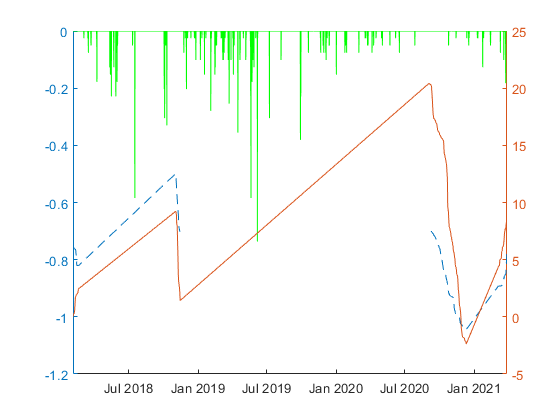

cd ..\
load('BLM31_AirPresCor.mat')
well = BLM31;

well = retime(well, "daily",'mean');
well.SoilTemp_C = smoothdata(well.SoilTemp_C,'movmedian','SmoothingFactor',0.05,...
    'SamplePoints',well.Date_Time_MDT);
well.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor = ...
    smoothdata(well.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor,...
    'movmedian','SmoothingFactor',0.05,'SamplePoints',well.Date_Time_MDT);

well = well(well.Date_Time_MDT >= datetime('2018-02-03','InputFormat','yyyy-MM-dd') , :);

idx = well.Date_Time_MDT >= datetime('2018-02-19','InputFormat','yyyy-MM-dd') & ...
    well.Date_Time_MDT <= datetime('2018-11-01','InputFormat','yyyy-MM-dd');
well = well(~idx, :);

idx = well.Date_Time_MDT >= datetime('2018-11-15','InputFormat','yyyy-MM-dd') & ...
    well.Date_Time_MDT <= datetime('2020-09-01','InputFormat','yyyy-MM-dd');
well = well(~idx, :);

idx = well.Date_Time_MDT >= datetime('2020-12-12','InputFormat','yyyy-MM-dd') & ...
    well.Date_Time_MDT <= datetime('2021-03-05','InputFormat','yyyy-MM-dd');
well = well(~idx, :);

well = well(well.Date_Time_MDT <= datetime('2021-03-29','InputFormat','yyyy-MM-dd') , :);


figure
hold on
yyaxis left
plot(Bflat30min.Date_Time_MDT, -Bflat30min.PPT_mm/10, 'color', 'green')
plot(well.Date_Time_MDT, -well.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor)

yyaxis right
plot(well.Date_Time_MDT, well.SoilTemp_C)

xlim(well.Date_Time_MDT([1,end]))

BLM31 = well;
cd cropped\
save("BLM31clipped.mat", 'BLM31')

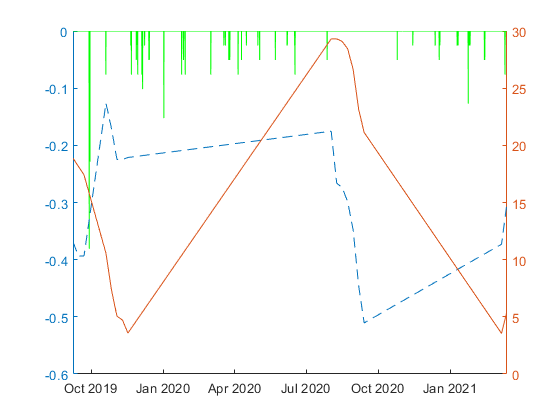

% cd ..\
load('BLM34_AirPresCor.mat')
well = BLM34;

well = retime(well, "weekly",'mean');
well.SoilTemp_C = smoothdata(well.SoilTemp_C,'movmedian','SmoothingFactor',0.05,...
    'SamplePoints',well.Date_Time_MDT);
well.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor = ...
    smoothdata(well.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor,...
    'movmedian','SmoothingFactor',0.05,'SamplePoints',well.Date_Time_MDT);

idx = well.Date_Time_MDT >= datetime('2019-09-26','InputFormat','yyyy-MM-dd') & ...
    well.Date_Time_MDT <= datetime('2019-10-16','InputFormat','yyyy-MM-dd');
well = well(~idx, :);
% 
idx = well.Date_Time_MDT >= datetime('2019-11-20','InputFormat','yyyy-MM-dd') & ...
    well.Date_Time_MDT <= datetime('2020-08-01','InputFormat','yyyy-MM-dd');
well = well(~idx, :);

idx = well.Date_Time_MDT >= datetime('2020-09-17','InputFormat','yyyy-MM-dd') & ...
    well.Date_Time_MDT <= datetime('2021-03-01','InputFormat','yyyy-MM-dd');
well = well(~idx, :);

idx = well.Date_Time_MDT >= datetime('2021-03-19','InputFormat','yyyy-MM-dd') & ...
    well.Date_Time_MDT <= datetime('2021-06-30','InputFormat','yyyy-MM-dd');
well = well(~idx, :);

figure
hold on
yyaxis left
plot(Bflat30min.Date_Time_MDT, -Bflat30min.PPT_mm/10, 'color', 'green')
plot(well.Date_Time_MDT, -well.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor)

yyaxis right
plot(well.Date_Time_MDT, well.SoilTemp_C)

xlim(well.Date_Time_MDT([1,end]))

BLM34 = well;
cd cropped\
save("BLM34clipped.mat", 'BLM34')

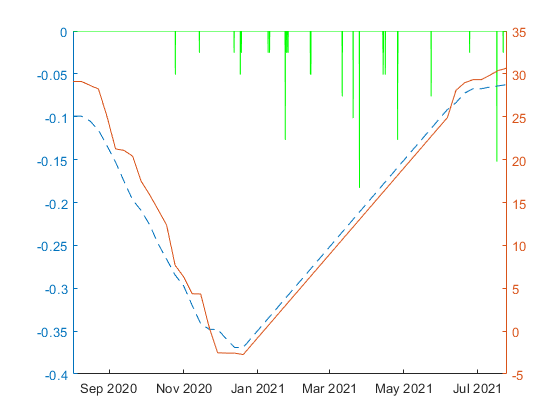

cd ..\
load('BLM37_AirPresCor.mat')
well = BLM37;

well = retime(well, "weekly",'mean');
well.SoilTemp_C = smoothdata(well.SoilTemp_C,'movmedian','SmoothingFactor',0.05,...
    'SamplePoints',well.Date_Time_MDT);
well.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor = ...
    smoothdata(well.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor,...
    'movmedian','SmoothingFactor',0.05,'SamplePoints',well.Date_Time_MDT);

well = well(well.Date_Time_MDT >= datetime('2020-08-01','InputFormat','yyyy-MM-dd') , :);

idx = well.Date_Time_MDT >= datetime('2020-12-27','InputFormat','yyyy-MM-dd') & ...
    well.Date_Time_MDT <= datetime('2021-06-01','InputFormat','yyyy-MM-dd');
well = well(~idx, :);

figure
hold on
yyaxis left
plot(Bflat30min.Date_Time_MDT, -Bflat30min.PPT_mm/10, 'color', 'green')
plot(well.Date_Time_MDT, -well.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor)

yyaxis right
plot(well.Date_Time_MDT, well.SoilTemp_C)

xlim(well.Date_Time_MDT([1,end]))

BLM37 = well;
cd cropped\
save("BLM37clipped.mat", 'BLM37')

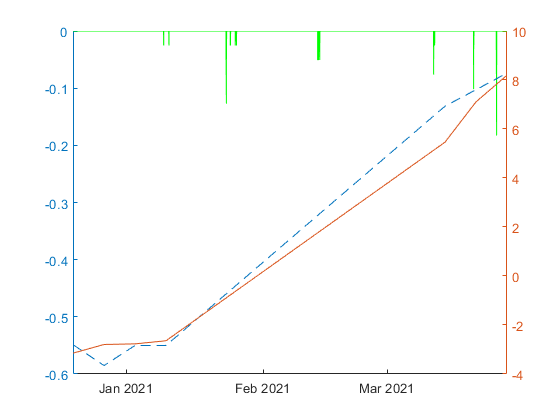

cd ..\
load('BLM43A_AirPresCor.mat')
well = BLM43A;

well = retime(well, "weekly",'mean');
well.SoilTemp_C = smoothdata(well.SoilTemp_C,'movmedian','SmoothingFactor',0.05,...
    'SamplePoints',well.Date_Time_MDT);
well.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor = ...
    smoothdata(well.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor,...
    'movmedian','SmoothingFactor',0.05,'SamplePoints',well.Date_Time_MDT);

idx = well.Date_Time_MDT >= datetime('2021-01-17','InputFormat','yyyy-MM-dd') & ...
    well.Date_Time_MDT <= datetime('2021-03-07','InputFormat','yyyy-MM-dd');
well = well(~idx, :);
% 
well = well(well.Date_Time_MDT <= datetime('2021-04-01','InputFormat','yyyy-MM-dd') , :);

figure
hold on
yyaxis left
plot(Bflat30min.Date_Time_MDT, -Bflat30min.PPT_mm/10, 'color', 'green')
plot(well.Date_Time_MDT, -well.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor)

yyaxis right
plot(well.Date_Time_MDT, well.SoilTemp_C)

xlim(well.Date_Time_MDT([1,end]))

BLM43A = well;
cd cropped\
save("BLM43Aclipped.mat", 'BLM43A')

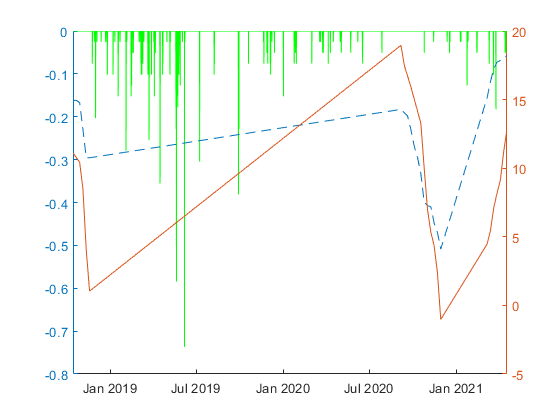

cd ..\
load('BLM45_AirPresCor.mat')
well = BLM45;

well = retime(well, "weekly",'mean');
well.SoilTemp_C = smoothdata(well.SoilTemp_C,'movmedian','SmoothingFactor',0.05,...
    'SamplePoints',well.Date_Time_MDT);
well.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor = ...
    smoothdata(well.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor,...
    'movmedian','SmoothingFactor',0.05,'SamplePoints',well.Date_Time_MDT);

well = well(well.Date_Time_MDT >= datetime('2018-10-14','InputFormat','yyyy-MM-dd') , :);

idx = well.Date_Time_MDT >= datetime('2018-11-19','InputFormat','yyyy-MM-dd') & ...
    well.Date_Time_MDT <= datetime('2020-09-05','InputFormat','yyyy-MM-dd');
well = well(~idx, :);
% 
idx = well.Date_Time_MDT >= datetime('2020-12-06','InputFormat','yyyy-MM-dd') & ...
    well.Date_Time_MDT <= datetime('2021-03-06','InputFormat','yyyy-MM-dd');
well = well(~idx, :);

well = well(well.Date_Time_MDT <= datetime('2021-04-18','InputFormat','yyyy-MM-dd') , :);

figure
hold on
yyaxis left
plot(Bflat30min.Date_Time_MDT, -Bflat30min.PPT_mm/10, 'color', 'green')
plot(well.Date_Time_MDT, -well.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor)

yyaxis right
plot(well.Date_Time_MDT, well.SoilTemp_C)

xlim(well.Date_Time_MDT([1,end]))

BLM45 = well;
cd cropped\
save("BLM45clipped.mat", 'BLM45')

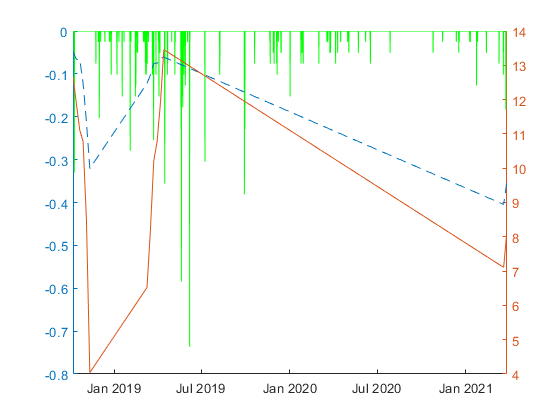

cd ..\
load('BLM50B_AirPresCor.mat')
well = BLM50B;

well = retime(well, "weekly",'mean');
well.SoilTemp_C = smoothdata(well.SoilTemp_C,'movmedian','SmoothingFactor',0.05,...
    'SamplePoints',well.Date_Time_MDT);
well.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor = ...
    smoothdata(well.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor,...
    'movmedian','SmoothingFactor',0.05,'SamplePoints',well.Date_Time_MDT);

well = well(well.Date_Time_MDT >= datetime('2018-10-07','InputFormat','yyyy-MM-dd') , :);
% 
idx = well.Date_Time_MDT >= datetime('2018-11-18','InputFormat','yyyy-MM-dd') & ...
    well.Date_Time_MDT <= datetime('2019-03-09','InputFormat','yyyy-MM-dd');
well = well(~idx, :);

idx = well.Date_Time_MDT >= datetime('2019-04-21','InputFormat','yyyy-MM-dd') & ...
    well.Date_Time_MDT <= datetime('2021-03-14','InputFormat','yyyy-MM-dd');
well = well(~idx, :);
% 
well = well(well.Date_Time_MDT <= datetime('2021-04-1','InputFormat','yyyy-MM-dd') , :);

figure
hold on
yyaxis left
plot(Bflat30min.Date_Time_MDT, -Bflat30min.PPT_mm/10, 'color', 'green')
plot(well.Date_Time_MDT, -well.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor)

yyaxis right
plot(well.Date_Time_MDT, well.SoilTemp_C)

xlim(well.Date_Time_MDT([1,end]))

BLM50B = well;
cd cropped\
save("BLM50Bclipped.mat", 'BLM50B')

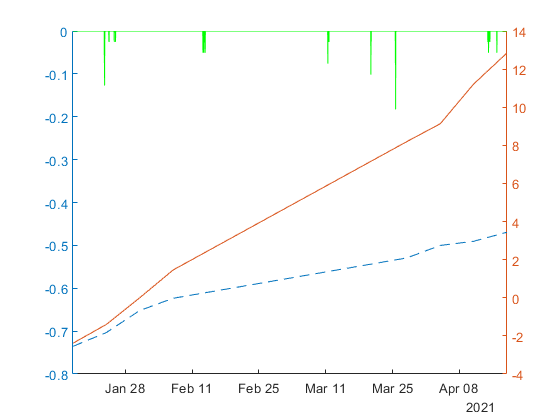

cd ..\
load('BLM53B_AirPresCor.mat')
well = BLM53B;

well = retime(well, "weekly",'mean');
well.SoilTemp_C = smoothdata(well.SoilTemp_C,'movmedian','SmoothingFactor',0.05,...
    'SamplePoints',well.Date_Time_MDT);
well.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor = ...
    smoothdata(well.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor,...
    'movmedian','SmoothingFactor',0.05,'SamplePoints',well.Date_Time_MDT);

well = well(well.Date_Time_MDT >= datetime('2021-01-17','InputFormat','yyyy-MM-dd') , :);

idx = well.Date_Time_MDT >= datetime('2021-02-14','InputFormat','yyyy-MM-dd') & ...
    well.Date_Time_MDT <= datetime('2021-03-14','InputFormat','yyyy-MM-dd');
well = well(~idx, :);
% % 

idx = well.Date_Time_MDT >= datetime('2021-02-28','InputFormat','yyyy-MM-dd') & ...
    well.Date_Time_MDT <= datetime('2021-03-21','InputFormat','yyyy-MM-dd');
well = well(~idx, :);

well = well(well.Date_Time_MDT <= datetime('2021-04-19','InputFormat','yyyy-MM-dd') , :);

figure
hold on
yyaxis left
plot(Bflat30min.Date_Time_MDT, -Bflat30min.PPT_mm/10, 'color', 'green')
plot(well.Date_Time_MDT, -well.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor)

yyaxis right
plot(well.Date_Time_MDT, well.SoilTemp_C)

xlim(well.Date_Time_MDT([1,end]))

BLM53B = well;
cd cropped\
save("BLM53Bclipped.mat", 'BLM53B')

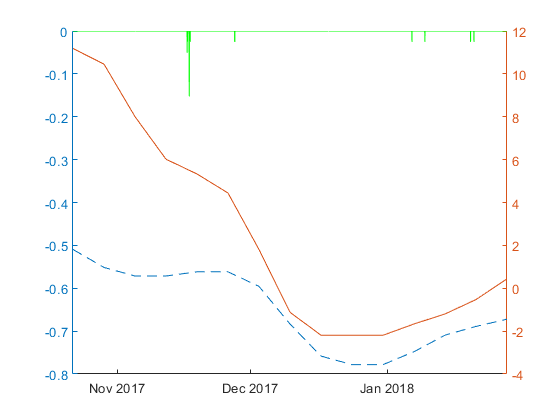

cd ..\
load('BLM12_AirPresCor.mat')
well = BLM12;

well = retime(well, "weekly",'mean');
well.SoilTemp_C = smoothdata(well.SoilTemp_C,'movmedian','SmoothingFactor',0.05,...
    'SamplePoints',well.Date_Time_MDT);
well.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor = ...
    smoothdata(well.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor,...
    'movmedian','SmoothingFactor',0.05,'SamplePoints',well.Date_Time_MDT);

well = well(well.Date_Time_MDT >= datetime('2017-10-21','InputFormat','yyyy-MM-dd') , :);

well = well(well.Date_Time_MDT <= datetime('2018-01-29','InputFormat','yyyy-MM-dd') , :);

figure
hold on
yyaxis left
plot(Bflat30min.Date_Time_MDT, -Bflat30min.PPT_mm/10, 'color', 'green')
plot(well.Date_Time_MDT, -well.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor)

yyaxis right
plot(well.Date_Time_MDT, well.SoilTemp_C)

xlim(well.Date_Time_MDT([1,end]))

BLM12 = well;
cd cropped\
save("BLM12clipped.mat", 'BLM12')

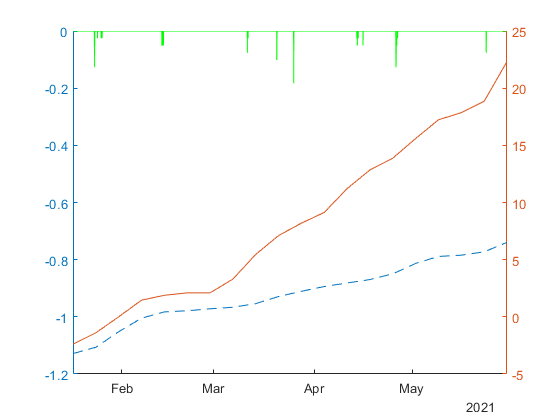

cd ..\
load('BLM63_AirPresCor.mat')
well = BLM63;

well = retime(well, "weekly",'mean');
well.SoilTemp_C = smoothdata(well.SoilTemp_C,'movmedian','SmoothingFactor',0.05,...
    'SamplePoints',well.Date_Time_MDT);
well.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor = ...
    smoothdata(well.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor,...
    'movmedian','SmoothingFactor',0.05,'SamplePoints',well.Date_Time_MDT);
% 
well = well(well.Date_Time_MDT >= datetime('2021-01-17','InputFormat','yyyy-MM-dd') , :);
% 
well = well(well.Date_Time_MDT <= datetime('2021-06-1','InputFormat','yyyy-MM-dd') , :);

figure
hold on
yyaxis left
plot(Bflat30min.Date_Time_MDT, -Bflat30min.PPT_mm/10, 'color', 'green')
plot(well.Date_Time_MDT, -well.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor)

yyaxis right
plot(well.Date_Time_MDT, well.SoilTemp_C)

xlim(well.Date_Time_MDT([1,end]))

BLM63 = well;
cd cropped\
save("BLM63clipped.mat", 'BLM63')

### Insufficient data for BLM64